LPV-RTAC class1

clear;
w_max = 0.6817;
w_min = 0;
alpha1 = 0;
alpha2 = alpha1;
beta1 = 0.6817;
beta2 = 0.3183;
eta1 = -0.6817;
nu1 = 0.6817;
eta2 = -0.6817;
nu2 = 0.6817;
eps_p = 0.2;
A0 = [0,1,0,0;
    -1,0,eps_p/pi,0;
    0,0,0,1;
    0,0,0,0];
B0 = [0,0,0,1]';
A1 = [0,0,0,0;
    0,0,eps_p,0;
    0,0,0,0;
    0,0,0,0];
B1 = zeros(4,1);
A2 = -A1;
B2 = B1;

第一类控制器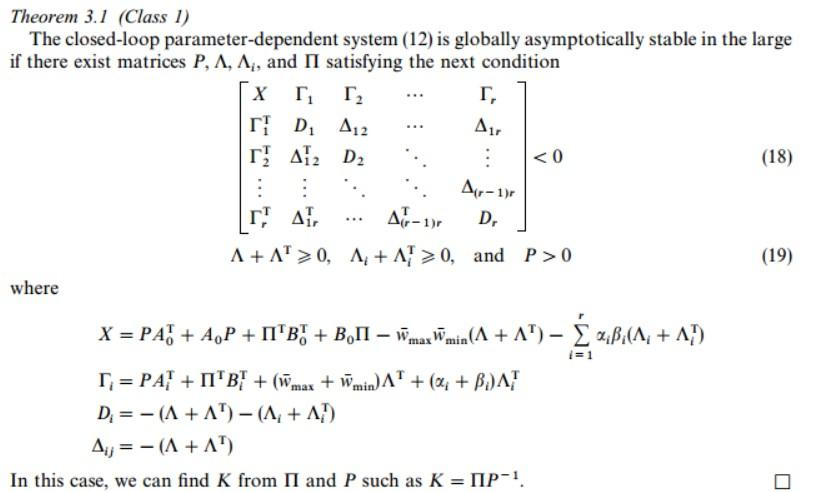

pvar z1 z2 z3 z4;
z=[z1;z2;z3;z4];
prog = sosprogram(z);
% [prog,P] = sospolymatrixvar(prog,monomials(z,0),[4,4],'symmetric');
[prog,P] = sospolymatrixvar(prog,monomials(z,0),[4,4]);
[prog,Pi] = sospolymatrixvar(prog,monomials(z,0),[1,4]);
[prog,Lamda] = sospolymatrixvar(prog,monomials(z,0),[4,4]);
[prog,Lamda1] = sospolymatrixvar(prog,monomials(z,0),[4,4]);
[prog,Lamda2] = sospolymatrixvar(prog,monomials(z,0),[4,4]);
X = P*A0'+A0*P+Pi'*B0'+B0*Pi-w_max*w_min*(Lamda+Lamda')...
    -alpha1*beta1*(Lamda1+Lamda1')-alpha2*beta2*(Lamda2+Lamda2');
Tao1 = P*A1'+Pi'*B1'+(w_max+w_min)*Lamda'+(alpha1+beta1)*Lamda1';
Tao2 = P*A2'+Pi'*B2'+(w_max+w_min)*Lamda'+(alpha2+beta2)*Lamda2';
D1 = -(Lamda+Lamda')-(Lamda1+Lamda1');
D2 = -(Lamda+Lamda')-(Lamda2+Lamda2');
Delta = -(Lamda+Lamda');
F = [X,Tao1,Tao2;
    Tao1',D1,Delta;
    Tao2',Delta',D2];
%添加约束
% prog = sosmatrixineq(prog, eps1, 'quadraticMineq');
prog = sosmatrixineq(prog, -F-(1e-8), 'quadraticMineq');
prog = sosmatrixineq(prog, (Lamda+Lamda'), 'quadraticMineq');
prog = sosmatrixineq(prog, (Lamda1+Lamda1'), 'quadraticMineq');
prog = sosmatrixineq(prog, (Lamda2+Lamda2'), 'quadraticMineq');
prog = sosmatrixineq(prog, P-(1e-5), 'quadraticMineq');
%求解
prog = sossolve(prog);

Size: 276  118
 
SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, Adaptive Step-Differentiation, theta = 0.250, beta = 0.500
Put 68 free variables in a quadratic cone
eqs m = 118, order n = 31, dim = 278, blocks = 7
nnz(A) = 378 + 0, nnz(ADA) = 13924, nnz(L) = 7021
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.10E+00 0.000
  1 :   1.05E-05 3.16E-01 0.000 0.2883 0.9000 0.9000   1.00  1  1  1.4E+00
  2 :   3.61E-06 1.04E-01 0.000 0.3301 0.9000 0.9000   1.00  1  1  4.6E-01
  3 :   1.76E-06 3.95E-02 0.000 0.3791 0.9000 0.9000   1.00  1  1  1.7E-01
  4 :   4.71E-07 8.01E-03 0.000 0.2026 0.9000 0.9000   1.00  1  1  3.5E-02
  5 :   3.13E-09 3.50E-05 0.000 0.0044 0.9990 0.9990   1.00  1  1  1.5E-04
  6 :   6.49E-16 8.76E-12 0.000 0.0000 1.0000 1.0000   1.00  1  1  3.6E-11

iter seconds digits       c*x               b*y
  6      0.2   5.2  0.0000000000e+00  6.4864885439e-16
|Ax-b| =   4.0e-11, [Ay-c]_+ =   5.3E-12,

%返回值
P = double(sosgetsol(prog,P));
Pi = double(sosgetsol(prog,Pi));
%状态反馈增益阵
K = Pi/P

K =     1.1096   -1.4276   -1.7622   -1.7163


保性能控制器

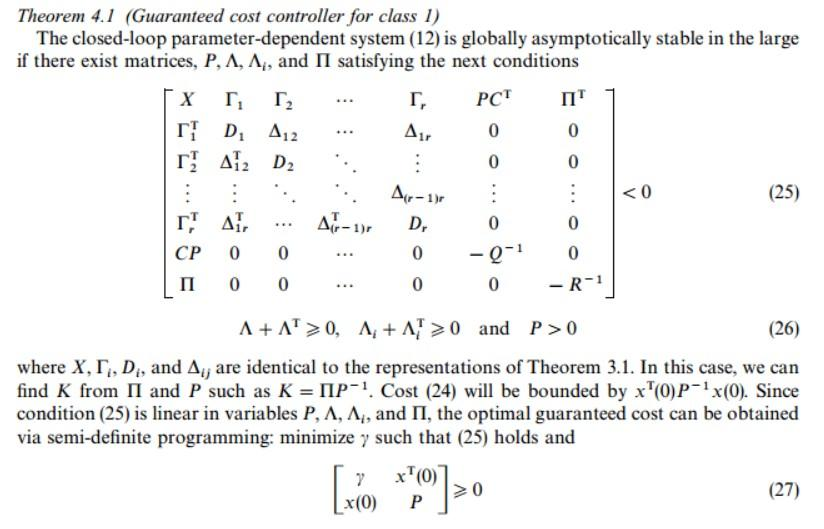

% [prog,gamma] = sospolymatrixvar(prog,monomials(z,0),[1,1]);
% C = [1,0,1,0];
% Q = 1;
% R = 1;
% F1 = [X,   Tao1,        Tao2,   P*C',            Pi';
%     Tao1',  D1,        Delta,   zeros(4,1),   zeros(4,1);
%     Tao2', Delta',       D2,    zeros(4,1),   zeros(4,1);
%      C*P,zeros(1,4), zeros(1,4),    -Q,           0;
%      Pi,zeros(1,4),  zeros(1,4),     0,           -R];
% x0 = [0,0,0,0]';
% M = [gamma,x0';
%     x0,P];
% %添加约束
% % prog = sosmatrixineq(prog, eps1, 'quadraticMineq');
% prog = sosmatrixineq(prog, -F1-(1e-8), 'quadraticMineq');
% prog = sosmatrixineq(prog, M, 'quadraticMineq');
% prog = sosmatrixineq(prog, (Lamda+Lamda'), 'quadraticMineq');
% prog = sosmatrixineq(prog, (Lamda1+Lamda1'), 'quadraticMineq');
% prog = sosmatrixineq(prog, (Lamda2+Lamda2'), 'quadraticMineq');
% prog = sosmatrixineq(prog, P-(1e-5), 'quadraticMineq');
% %设置目标问题min
% prog = sossetobj(prog, gamma);
% %求解
% prog = sossolve(prog);
% %返回值
% P = double(sosgetsol(prog,P));
% Pi = double(sosgetsol(prog,Pi));
% gamma = double(sosgetsol(prog,gamma))
% %状态反馈增益阵
% K = Pi/P